clear; clc;

## combine

X_nir900 = [zd_nir900; jd_nir900; nh_nir900; jh_nir900]; 
y_nir900 = [ones(25, 1); ones(25, 1)*2; ones(25, 1)*3; ones(25, 1)*4];


[~, p1] = min(abs(wavelengths900 - 1000));
[~, p2] = min(abs(wavelengths900 - 1800));
effwavelengths900 = wavelengths900(p1:p2);

X_nir900 = X_nir900(:, p1:p2);


X_nir_air900 = pre_airpls(X_nir900, 10e3);

X_nir_air_sg900 = pre_sgfilter(X_nir_air900, 15, 2, 0);

X_nir_air_sg_v900 = reshape(X_nir_air_sg900, 1, size(X_nir_air_sg900, 1)*size(X_nir_air_sg900, 2));
X_nir_air_sg_01_v900 = mapminmax(X_nir_air_sg_v900, 0, 1);
X_nir_air_sg_01900 = reshape(X_nir_air_sg_01_v900, size(X_nir_air_sg900, 1), size(X_nir_air_sg900, 2));
% X_nir_air_sg_snv = pre_snv(X_nir_air_sg);

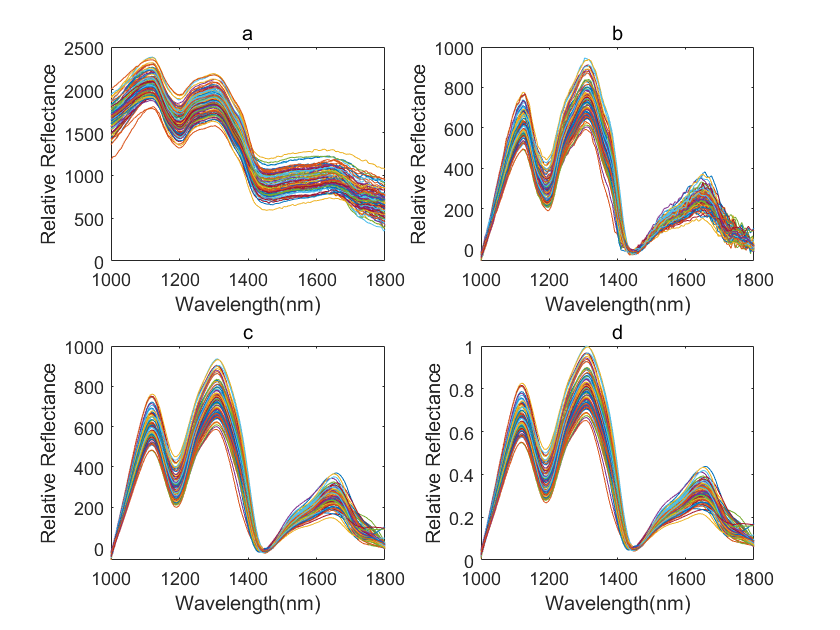

figure;
subplot(2,2,1);
for k = 1:size(X_nir900, 1)
    plot(effwavelengths900, X_nir900(k, :));
    hold on;
end 
xlim([1000, 1800])
xlabel('Wavelength(nm)')
ylabel('Relative Reflectance')
title('a')

subplot(2,2,2);
for k = 1:size(X_nir900, 1)
    plot(effwavelengths900, X_nir_air900(k, :));
    hold on;
end 
xlim([1000, 1800])
xlabel('Wavelength(nm)')
ylabel('Relative Reflectance')
title('b')

subplot(2,2,3);
for k = 1:size(X_nir900, 1)
    plot(effwavelengths900, X_nir_air_sg900(k, :));
    hold on;
end
xlim([1000, 1800])
xlabel('Wavelength(nm)')
ylabel('Relative Reflectance')
title('c')

subplot(2,2,4);
for k = 1:size(X_nir900, 1)
    plot(effwavelengths900, X_nir_air_sg_01900(k, :));
    hold on;
end 
xlim([1000, 1800])
xlabel('Wavelength(nm)')
ylabel('Relative Reflectance')
title('d')

% figure('Units','normalized','Position',[0, 0, 0.75, 1]);
% for k = 1:size(X_nir, 1)
%     plot(effwavelengths, X_nir(k, :), "LineWidth", 1);
%     hold on;
% end 
% xlim([400, 1000])
% xlabel('Wavelength(nm)')
% ylabel('Relative Reflectance')
% set(gca,'fontsize',30, 'FontWeight','bold');
% title("original NIR data")
% 
% figure('Units','normalized','Position',[0, 0, 0.75, 1]);
% for k = 1:size(X_nir, 1)
%     plot(effwavelengths, X_nir_sg1_snv(k, :), "LineWidth", 1);
%     hold on;
% end 
% xlim([400, 1000])
% xlabel('Wavelength(nm)')
% ylabel('Relative Reflectance')
% set(gca,'fontsize',30, 'FontWeight','bold');
% title('air & sg & norm NIR data')

y1 = find(y_nir900 == 1); 
y2 = find(y_nir900 == 2);
y3 = find(y_nir900 == 3);
y4 = find(y_nir900 == 4);

data = X_nir_air_sg_01900;
avedata_variety_nir900 = zeros(4, length(effwavelengths900));

avedata_variety_nir900(1, :) = mean(data(y1, :), 1);
avedata_variety_nir900(2, :) = mean(data(y2, :), 1);
avedata_variety_nir900(3, :) = mean(data(y3, :), 1);
avedata_variety_nir900(4, :) = mean(data(y4, :), 1);

avedata_variety_nir_merge = [avedata_variety_nir, avedata_variety_nir900];
effwavelengths_merge = [effwavelengths, effwavelengths900];

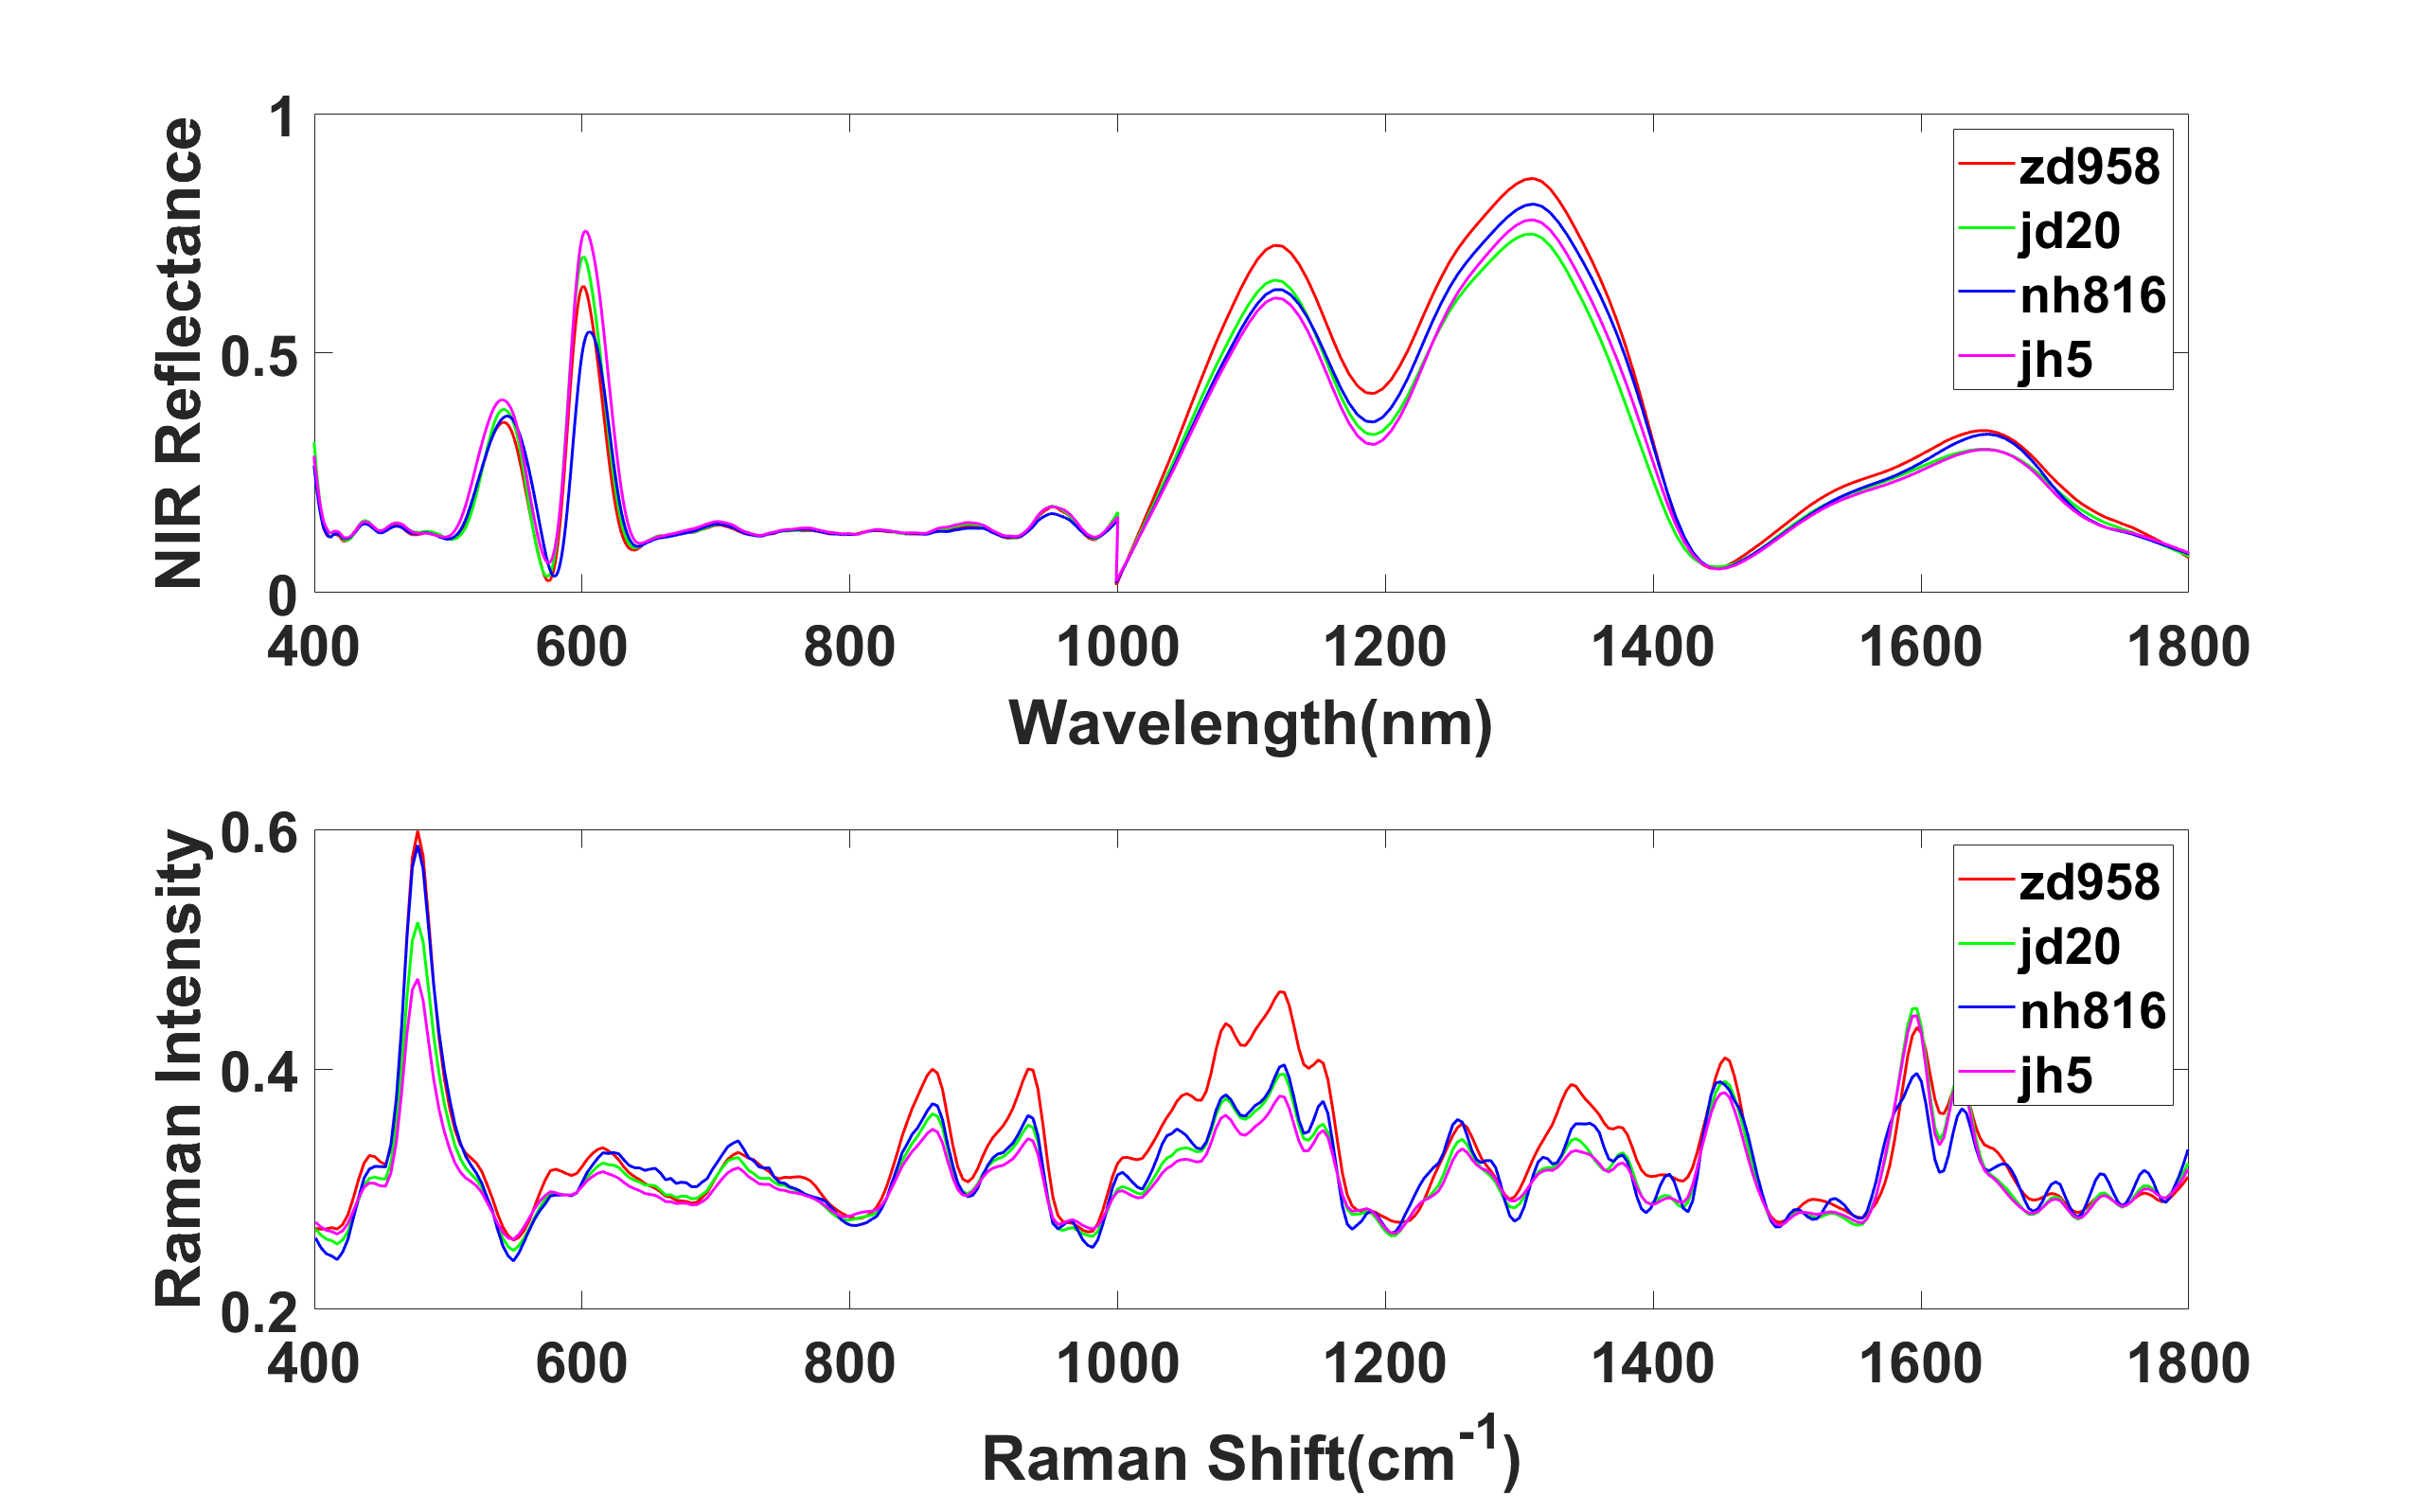


figure('Units','normalized','Position',[0, 0, 1, 1]);

subplot(2,1,1);
seed_varieties = ["zd958", "jd20", "nh816", "jh5"];
colors = ['r', 'g', 'b', 'm'];
for k = 1:length(seed_varieties)
    plot(effwavelengths_merge, avedata_variety_nir_merge(k, :), "Color", colors(k), "LineWidth", 1.5);
    hold on;
end


xlim([400, 1800])
xlabel('Wavelength(nm)')
ylabel('NIR Reflectance')
legend(seed_varieties) 
set(gca,'fontsize',30, 'FontWeight','bold');
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(2,1,2);

seed_varieties = ["zd958", "jd20", "nh816", "jh5"];
colors = ['r', 'g', 'b', 'm'];

for k = 1:length(seed_varieties)
    plot(effshift, avedata_variety(k, :), "Color", colors(k), "LineWidth", 1.5);
    hold on;
end

xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Raman Intensity')
legend(seed_varieties) 
set(gca,'fontsize',30, 'FontWeight','bold');